# Optimierung für Industrielogistiker

## Übungsaufgabe 6

Im Code unten finden Sie die nicht fertig gemachten Funktionen armijo, goldstein und wolfepowell, die den einzelnen Algorithmen auf Seiten 33 und 34 im Skriptum entsprechen. Programmieren Sie mindestens zwei dieser Methoden aus. Probieren Sie auch aus, welchen Einfluss die einzelnen Parameter und die Wahl der Startlösung haben. Benützen Sie dafür den in der beigefügten Datei stehenden Code.

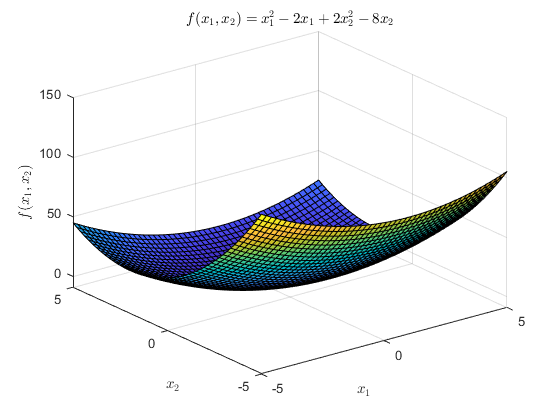

clear variablse;
clc;

f = @(x, y) x.^2 - 2 * x + 2 * y.^2 - 8 * y;
x = linspace(-5, 5, 50);
y = linspace(-5, 5, 50);
[X, Y] = meshgrid(x, y);
Z = f(X, Y);
surf(X, Y, Z);
title('$f(x_1, x_2) = x_1^2 - 2 x_1 + 2 x_2^2 - 8 x_2$', 'interpreter', 'latex');
xlabel('$x_1$', 'interpreter', 'latex');
ylabel('$x_2$', 'interpreter', 'latex');
zlabel('$f(x_1, x_2)$', 'interpreter', 'latex');


EPSILON = 1e-8;
MAX_NUMBER_OF_ITERATIONS = 10000;
f = @(x) x(1).^2 - 2 * x(1) + 2 * x(2).^2 - 8 * x(2);
gradf = @(x) [2 * x(1) - 2; 4 * x(2) - 8];
P_0 = [1.5; 1.5];

[p, numberofiterations] = gradientdescent(1, true, f, gradf, P_0, EPSILON, MAX_NUMBER_OF_ITERATIONS);
disp('Armijo:');

Armijo:


disp(['p:                    [', num2str(p', '%.8f '), ']']);

p:                    [1.00000000 2.00000000]


disp(['number of iterations: ', num2str(numberofiterations)]);

number of iterations: 27



disp('______________________________________________________________________________');

______________________________________________________________________________



[p, numberofiterations] = gradientdescent(2, true, f, gradf, P_0, EPSILON, MAX_NUMBER_OF_ITERATIONS);
disp('Goldstein:');

Goldstein:


disp(['p:                    [', num2str(p', '%.8f '), ']']);

p:                    [1.00000000 2.00000000]


disp(['number of iterations: ', num2str(numberofiterations)]);

number of iterations: 2



disp('______________________________________________________________________________');

______________________________________________________________________________



[p, numberofiterations] = gradientdescent(3, true, f, gradf, P_0, EPSILON, MAX_NUMBER_OF_ITERATIONS);
disp('Wolfe-Powell:');

Wolfe-Powell:


disp(['p:                    [', num2str(p', '%.8f '), ']']);

p:                    [NaN]


disp(['number of iterations: ', num2str(numberofiterations)]);

number of iterations: 10000


function [p, numberofiterations] = gradientdescent(lambdaestimation, MINIMIZE, f, gradf, P_0, EPSILON, MAX_NUMBER_OF_ITERATIONS)
    p = P_0;
    for i = 0:MAX_NUMBER_OF_ITERATIONS - 1
        gradfp = gradf(p);
        if norm(gradfp) < EPSILON
            numberofiterations = i;
            return;
        end
        switch lambdaestimation
            case 1
                lambda = armijo(MINIMIZE, f, gradf, p, 0.9, 0.5, MAX_NUMBER_OF_ITERATIONS);
            case 2
                lambda = goldstein(MINIMIZE, f, gradf, p, 1, 0.4, MAX_NUMBER_OF_ITERATIONS);
            case 3
                lambda = wolfepowell(MINIMIZE, f, gradf, p, 0.25, 0.25, 2, 1, 0.4, 0.5, MAX_NUMBER_OF_ITERATIONS);
        end
        if isnan(lambda)
            p = NaN;
            numberofiterations = i + 1;
            return;
        end
        if MINIMIZE
            d = -gradfp;
        else
            d = gradfp;
        end
        p = p + lambda * d;
    end
    numberofiterations = MAX_NUMBER_OF_ITERATIONS;
    p = NaN;
end

function [lambda] = armijo(MINIMIZE, f, gradf, P_0, ALPHA, SIGMA, MAX_NUMBER_OF_ITERATIONS)
    lambda = 1;
    
    if MINIMIZE
        d = -gradf(P_0);
    else 
        d = gradf(P_0);
    end
    
    for i = 0:MAX_NUMBER_OF_ITERATIONS
        x = P_0 + (ALPHA^i)*d;
        it_value = f(x);
        it_limit = f(P_0) + SIGMA * ALPHA^i * (transpose(gradf(P_0))*d);
        
        if it_value <= it_limit
            lambda = ALPHA^i;
            return;
        end
    end
    lambda = nan;
end

function [lambda] = goldstein(MINIMIZE, f, gradf, P_0, lambdao, SIGMA, MAX_NUMBER_OF_ITERATIONS)
    lambdau = 0;
    numberofIterations = 0;
    
    if MINIMIZE
        d = -gradf(P_0);
    else 
        d = gradf(P_0);
    end
    
    [phi, phio, phiu] = definePhiFunctions(f, gradf, P_0, d, SIGMA);
    
    for i = numberofIterations: MAX_NUMBER_OF_ITERATIONS
        if phi(lambdao) < phiu(lambdao)
            lambdau = lambdao;
            lambdao = 2 * lambdao;
        else
            numberofIterations = i;
            break;            
        end
    end
    
    if phi(lambdao) <= phio(lambdao)
        lambda = lambdao;
        return;
    end
    
    for i = numberofIterations: MAX_NUMBER_OF_ITERATIONS
        lambda = (lambdau + lambdao)/2;
                
        phiu_value = phiu(lambda);
        phi_value = phi(lambda);
        phio_value = phio(lambda);
        
        if phiu_value <= phi_value && phi_value <= phio_value
            return;
        end
        
        if phi(lambda) < phiu(lambda)
            lambdau = lambda;
        elseif phi(lambda) > phio(lambda)
            lambdao = lambda;
        end
       
    end
end

function [phi, phio, phiu] = definePhiFunctions(f, gradf, P_0, d, SIGMA)
    p = @(lambda) P_0 + lambda * d;
    phi = @(lambda) f(p(lambda));
    phi_s = @(lambda) transpose(gradf(p(lambda))) * d;
    phio = @(lambda) phi(0) + SIGMA * lambda * phi_s(0);
    phiu = @(lambda) phi(0) + (1 - SIGMA) * lambda * phi_s(0);
    
end

function [lambda] = wolfepowell(MINIMIZE, f, gradf, P_0, ALPHA_1, ALPHA_2, GAMMA, lambda, SIGMA, RHO, MAX_NUMBER_OF_ITERATIONS) %l. 1
    lambda = 1;
end